# V768 - Measuring Vision with Psychophysics

## Lab 11 - Ideal Observer Models

In earlier labs, you measured human performance on various visual tasks. But how do we know if humans are performing well? Against what benchmark should we compare our results?

The answer comes from **ideal observer theory**. An ideal observer is a theoretical device that performs a task as well as is **statistically possible** given the information in the stimulus. By comparing human performance to ideal performance, we can quantify how much information humans lose during visual processing. This measure is called **efficiency**, and it tells us something fundamental about the processing limitations of the visual system.

In this lab, you will (1) build an ideal observer for a contrast detection task, (2) simulate its performance using matched-filter detection theory, and (3) measure your own performance on the same task. You will then compute your perceptual efficiency by comparing your threshold to the ideal observer's threshold.

Learning Outcomes (i.e., what you will be able to do at the end of this lab)

- Define what an ideal observer is and explain why it provides a useful benchmark for human performance.

- Implement a matched-filter detector for a 2AFC contrast detection task.

- Simulate psychophysical trials and construct a psychometric curve from simulation results.

- Derive or verify the relationship between signal energy, noise variance, and ideal d'.

- Compute human efficiency by comparing your detection performance to the ideal observer.

Questions

- Does the ideal observer simulation match the analytical prediction? What sources of error might explain any discrepancies?

- What happens to the psychometric curve if you double the noise standard deviation? What about if you double the spatial frequency of the Gabor?

- What is your measured efficiency? How does it compare to typical values (10-50%) for simple detection tasks?

- Would you expect efficiency to change with very high spatial frequencies (near the resolution limit)? Why or why not?

## Background: What is an Ideal Observer?

An ideal observer represents the **best possible performance** on a given task, assuming (1) the observer knows the task perfectly, (2) the observer uses all available stimulus information, and (3) the observer performs optimal inference on that information. In essence, an ideal observer is a statistical device with perfect knowledge and unlimited computational power.

Why is this useful? Because human performance is almost **always** worse than ideal performance. The gap between human and ideal performance—measured as **efficiency**— tells us about the **limiting factors** in human vision. These limits might arise from:

- **Optical blur** (limits on focus and resolution)

- **Photon noise** (random fluctuations in light capture)

- **Neural noise** (variability in neural responses)

- **Inefficient neural coding** (the brain doesn't use all the information available)

- **Limited attention** (we don't always look at the right place)

By measuring efficiency, we can begin to understand which of these factors is limiting performance in a given task.

## The Task: 2AFC Contrast Detection in Noise

You will perform (and simulate) a **two-alternative forced choice (2AFC)** contrast detection task. On each trial:

1. You see two intervals (separated by a brief pause) 2. Both intervals contain independent samples of white Gaussian noise 3. In **one** interval, a small Gabor patch (a sine-wave grating windowed by a Gaussian) is **added** to the noise 4. Your task is to indicate which interval contained the signal (Gabor patch) 5. You must choose, even if you are guessing

Because this is a 2AFC task, chance performance is 50% correct. A well-designed experiment will include a range of signal contrasts, from very weak (near threshold) to very strong (nearly 100% correct). The resulting plot of percent correct vs. contrast forms a **psychometric curve**.

## The Ideal Strategy: Matched Filtering

If you **knew** exactly what the signal looked like and **knew** that the noise was Gaussian, what would be the optimal strategy?

The answer is **matched filtering**. For each interval, compute the dot product (correlation at zero lag) between the noisy image and the signal template. Choose the interval with the **larger** response. Mathematically:


$$r_i = \sum \sum \text{image}_i \times S$$


where $\text{image}_i$ is interval $i$ and $S$ is the signal template.

This is an optimal strategy: no other detector can achieve higher percent correct in Gaussian noise. Therefore, a matched filter gives us the **ideal observer** for this task.

## Ideal Performance: The Role of Signal Energy and Noise Variance

How well does an ideal matched-filter observer perform? Signal detection theory provides a closed-form answer.

For a matched filter in white Gaussian noise, the decision variable in each interval is normally distributed. The key insight is that the **signal-to-noise ratio** (SNR) determines performance. Specifically:


$$d'_{\text{ideal}} = \sqrt{\text{SNR}} = \sqrt{\frac{E}{\sigma^2}} = \frac{c}{\sigma_{\text{noise}}}$$


where: * $E$ = signal energy (sum of squared signal values) * $\sigma^2$ = noise variance per pixel * $c$ = signal contrast * $\sigma_{\text{noise}}$ = noise standard deviation

Since we will normalize the signal template to unit energy ($\sum S^2 = 1$), we have $d'_{\text{ideal}} = c / \sigma_{\text{noise}}$.

In a 2AFC task, this d' value translates to percent correct via the cumulative normal distribution:


$$\text{PC} = \Phi\left(\frac{d'}{\sqrt{2}}\right)$$


where $\Phi$ is the standard normal CDF.

## Efficiency: Comparing Human to Ideal

Once you have measured your own performance and the ideal observer's performance, you can compute your **efficiency**:


$$\eta = \left(\frac{d'_{\text{human}}}{d'_{\text{ideal}}}\right)^2 = \left(\frac{c_{\text{ideal}}}{c_{\text{human}}}\right)^2$$


Efficiency is a number between 0 and 1 (or 0-100%). An efficiency of 100% means you are performing as well as the ideal observer. An efficiency of 10% means the ideal observer only needs 10% of the contrast that you need to reach the same detection threshold. Typical values for simple detection tasks range from 10-50%.

## =========================================================================

## A. PART 1: BUILDING THE STIMULUS

## =========================================================================

In this section, we will create the signal template (a Gabor patch) and generate example stimulus pairs at different contrasts so you can visualize what the task looks like.

clear; close all; clc;

## A.1: Create the signal template

First, we need to generate a Gabor patch: a sinusoidal grating (vertical orientation) windowed by a Gaussian envelope. This will serve as our signal template $S$.

% Stimulus parameters
img_size = 64;              % Image size (pixels)
spatial_freq = 4;           % Cycles per image
orientation = 0;            % Degrees (0 = vertical grating)
gabor_sigma = 10;           % Gaussian envelope std dev (pixels)
phase = 0;                  % Radians
noise_sd = 0.2;             % Noise standard deviation (matches PsychoPy noise contrast)

% Generate coordinate grid
[x, y] = meshgrid(1:img_size, 1:img_size);
x = x - img_size/2;
y = y - img_size/2;

% Rotate coordinates for arbitrary orientation
x_rot = x * cosd(orientation) - y * sind(orientation);
y_rot = x * sind(orientation) + y * cosd(orientation);

% Create the sinusoidal grating component
wavelength = img_size / spatial_freq;
grating = sin(2*pi*x_rot/wavelength + phase);

% Apply Gaussian envelope (windowing)
gaussian_envelope = exp(-(x.^2 + y.^2) / (2 * gabor_sigma^2));
S = grating .* gaussian_envelope;

% Normalize to unit energy: sum(S^2) = 1
% This makes it easy to scale signal contrast later
S = S / sqrt(sum(S(:).^2));
S = S / max(S(:));

fprintf(['Part A: Building the Stimulus\n' ...
    '  Image size: %d x %d pixels\n'...
    '  Spatial frequency: %.1f cycles/image\n'...
    '  Gabor sigma: %.1f pixels\n'...
    '  Signal energy (sum S^2): %.4f\n'...
    '  Noise SD: %.2f\n\n'],img_size, img_size,spatial_freq,gabor_sigma, sum(S(:).^2), noise_sd);

Part A: Building the Stimulus
  Image size: 64 x 64 pixels
  Spatial frequency: 4.0 cycles/image
  Gabor sigma: 10.0 pixels
  Signal energy (sum S^2): 184.3328
  Noise SD: 0.20



## A.2: Generate example stimulus pairs at different contrasts

Now let's generate a few example trials at low and high contrast so you can see what the stimulus looks like. The question is: can you see the signal?

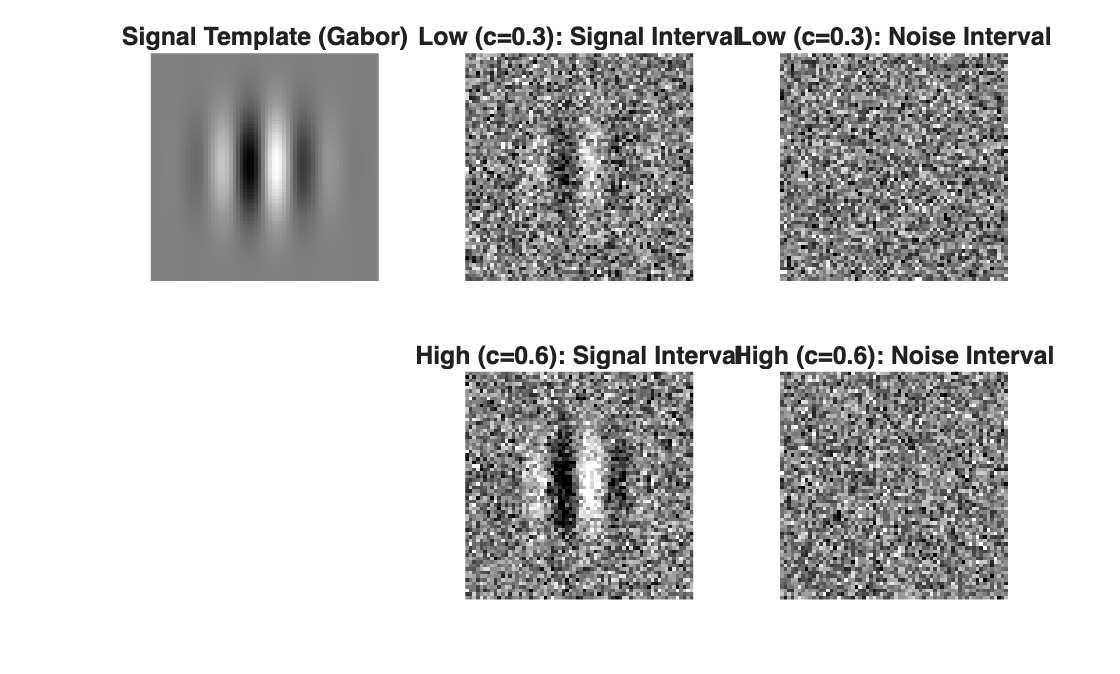

rng(42);  % for reproducibility

% For visualization, use reduced noise so the signal is visible
vis_noise_sd = noise_sd;  % Lower noise for visualization only

% Low contrast example (visible for demonstration)
contrast_lo = 0.3;
N1_lo = vis_noise_sd * randn(img_size);
N2_lo = vis_noise_sd * randn(img_size);
signal_interval_lo = 1;

stim1_lo = 0.5 + N1_lo + (signal_interval_lo == 1) * contrast_lo * S;
stim2_lo = 0.5 + N2_lo + (signal_interval_lo == 2) * contrast_lo * S;

% High contrast example (very clearly visible)
contrast_hi = 0.6;
N1_hi = vis_noise_sd * randn(img_size);
N2_hi = vis_noise_sd * randn(img_size);
signal_interval_hi = 1;

stim1_hi = 0.5 + N1_hi + (signal_interval_hi == 1) * contrast_hi * S;
stim2_hi = 0.5 + N2_hi + (signal_interval_hi == 2) * contrast_hi * S;

% Visualize
figure('Name', 'Part A: Example Stimuli');
colormap gray;

% Template
subplot(2, 3, 1);
imagesc(S, [-max(abs(S(:))), max(abs(S(:)))]); axis image off;
title('Signal Template (Gabor)');

% Low contrast stimuli
subplot(2, 3, 2);
imagesc(stim1_lo, [0, 1]); axis image off;
title(sprintf('Low (c=%.1f): Signal Interval', contrast_lo));

subplot(2, 3, 3);
imagesc(stim2_lo, [0, 1]); axis image off;
title(sprintf('Low (c=%.1f): Noise Interval', contrast_lo));

% High contrast stimuli
subplot(2, 3, 5);
imagesc(stim1_hi, [0, 1]); axis image off;
title(sprintf('High (c=%.1f): Signal Interval', contrast_hi));

subplot(2, 3, 6);
imagesc(stim2_hi, [0, 1]); axis image off;
title(sprintf('High (c=%.1f): Noise Interval', contrast_hi));

axis off;


drawnow;

**Looking at the images above:** Can you see the signal in the low-contrast trials? How about the high-contrast trials? What does the signal look like—a vertical grating (stripes)? Notice the differences in visibility as contrast increases.

## =========================================================================

## B. PART 2: SIMULATING THE IDEAL OBSERVER

## =========================================================================

Now we will implement the matched-filter ideal observer and simulate thousands of trials across a range of signal contrasts.

## B.1: The matched-filter detector

The ideal observer's strategy is simple: for each interval, compute the response to the signal template (the dot product), and choose the interval with the larger response.

This is mathematically optimal for Gaussian noise because it is a sufficient statistic for the detection decision.

% Simulation parameters
contrast_levels = [.0001, 0.001, 0.01, 0.03, 0.1, 0.3, 0.6];  % matches PsychoPy conditions
n_contrasts = length(contrast_levels);
n_trials_per_contrast = 500;

% Pre-allocate arrays for results
percent_correct = zeros(1, n_contrasts);
n_correct = zeros(1, n_contrasts);

fprintf(['Part B: Simulating the Ideal Observer\n' ...
    '  Number of contrast levels: %d\n'...
    '  Trials per level: %d\n' ...
    '  Total trials: %d\n\n'], n_contrasts,n_trials_per_contrast, n_contrasts * n_trials_per_contrast);

Part B: Simulating the Ideal Observer
  Number of contrast levels: 7
  Trials per level: 500
  Total trials: 3500



## B.2: Run the simulation

rng(123);  % for reproducibility

% Loop over contrast levels
for c_idx = 1:n_contrasts
    c = contrast_levels(c_idx);
    
    % Run 500 trials at this contrast
    for trial = 1:n_trials_per_contrast
        % Generate two independent noise fields
        N1 = noise_sd * randn(img_size);
        N2 = noise_sd * randn(img_size);
        
        % Randomly choose which interval (1 or 2) contains the signal
        signal_interval = randi(2);
        
        % Create the two stimulus intervals (baseline 0.5 + noise + signal)
        if signal_interval == 1
            stim1 = 0.5 + N1 + c * S;
            stim2 = 0.5 + N2;
        else
            stim1 = 0.5 + N1;
            stim2 = 0.5 + N2 + c * S;
        end
        
        % Compute matched-filter response for each interval
        r1 = sum(stim1(:) .* S(:));
        r2 = sum(stim2(:) .* S(:));
        
        % Ideal observer chooses the interval with larger response
        choice = (r2 > r1) + 1;  % choice = 1 or 2
        
        % Record if correct
        if choice == signal_interval
            n_correct(c_idx) = n_correct(c_idx) + 1;
        end
    end
    
    % Compute percent correct for this contrast level
    percent_correct(c_idx) = 100 * n_correct(c_idx) / n_trials_per_contrast;
    fprintf('  Contrast c=%.2f: %d/%d correct (%.1f%%)\n', ...
        c, n_correct(c_idx), n_trials_per_contrast, percent_correct(c_idx));
end

  Contrast c=0.00: 259/500 correct (51.8%)
  Contrast c=0.00: 254/500 correct (50.8%)
  Contrast c=0.01: 341/500 correct (68.2%)
  Contrast c=0.03: 481/500 correct (96.2%)
  Contrast c=0.10: 500/500 correct (100.0%)
  Contrast c=0.30: 500/500 correct (100.0%)
  Contrast c=0.60: 500/500 correct (100.0%)



fprintf('\nSimulation complete.\n\n');


Simulation complete.



## B.3: Plot the psychometric curve

The resulting curve plots percent correct as a function of signal contrast. At c=0 (no signal), the ideal observer should perform at chance (50%). As contrast increases, performance should rise smoothly toward 100%.

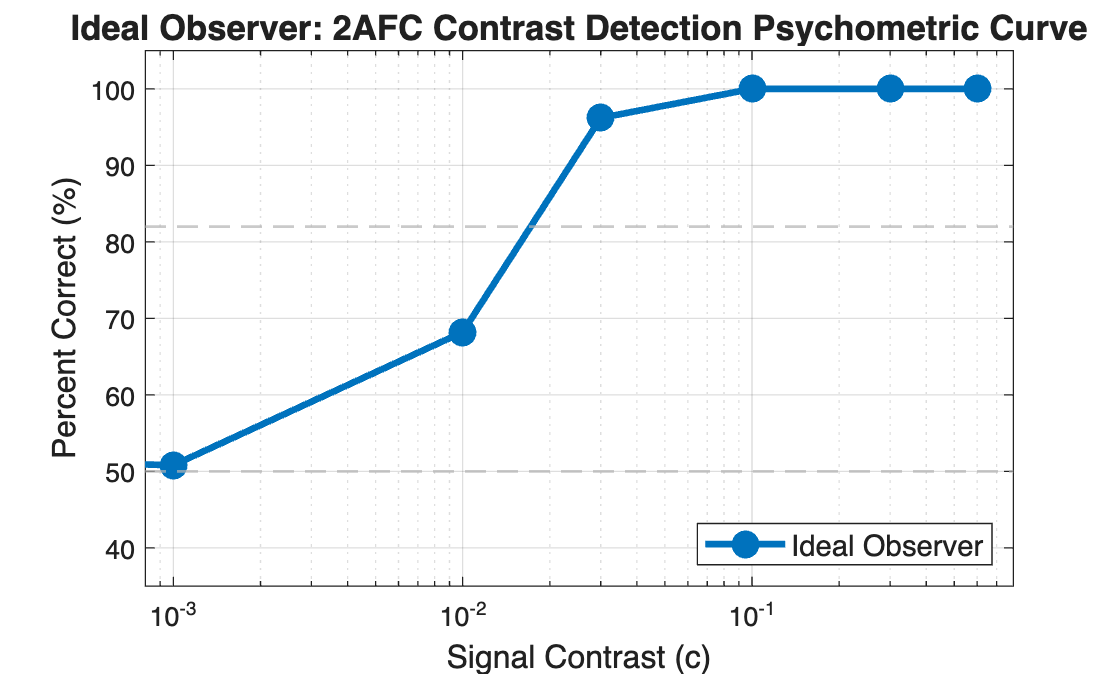

figure('Name', 'Part B: Ideal Observer Psychometric Curve');
plot(contrast_levels, percent_correct, 'o-', 'LineWidth', 2.5, 'MarkerSize', 8, ...
    'Color', [0, 0.447, 0.741], 'MarkerFaceColor', [0, 0.447, 0.741]);
hold on;

% Add reference lines
yline(50, 'LineStyle', '--', 'Color', [0.7 0.7 0.7], 'LineWidth', 1);
yline(82, 'LineStyle', '--', 'Color', [0.7 0.7 0.7], 'LineWidth', 1);

xlabel('Signal Contrast (c)', 'FontSize', 12);
ylabel('Percent Correct (%)', 'FontSize', 12);
title('Ideal Observer: 2AFC Contrast Detection Psychometric Curve', 'FontSize', 13);
set(gca, 'XScale', 'log');
grid on;
ylim([35, 105]);
xlim([0.0008, 0.8]);
legend('Ideal Observer', 'Location', 'southeast', 'FontSize', 11);


drawnow;

**Look at this curve:** Does it have the shape you expected? Where does the ideal observer reach 82% correct? (This is a conventional threshold—halfway between chance at 50% and the top of the curve.)

## =========================================================================

## C. PART 3: FITTING AND VERIFICATION AGAINST THEORY

## =========================================================================

Now let's fit a psychometric curve to the simulated data and compare it to our analytical predictions based on signal detection theory.

## C.1: Fit a cumulative Gaussian psychometric function

We'll fit the model


$$\text{PC} = \Phi\left(\frac{c - c_{50}}{\text{slope}}\right)$$


where $\Phi$ is the standard normal CDF, $c_{50}$ is the threshold (contrast at 50% above chance), and slope controls how steeply performance rises.

% Define the fit function
fit_fun = @(params) sum((percent_correct - 100*normcdf((contrast_levels - params(1))/params(2))).^2);

% Initial guess for parameters
params0 = [0.2, 0.05];  % [threshold, slope]

% Fit using fminsearch (minimizes squared error)
options = optimset('Display', 'off');
fitted_params = fminsearch(fit_fun, params0, options);

threshold_fitted = fitted_params(1);
slope_fitted = fitted_params(2);

fprintf('Fitted psychometric function:\n');

Fitted psychometric function:


fprintf('  Threshold (c50): %.4f\n', threshold_fitted);

  Threshold (c50): 0.0002


fprintf('  Slope: %.4f\n\n', slope_fitted);

  Slope: 0.0188




% Compute threshold at 82% correct using the fitted curve
threshold_82 = threshold_fitted + slope_fitted * norminv(0.82);
fprintf('  Threshold at 82%% correct: %.4f\n\n', threshold_82);

  Threshold at 82% correct: 0.0174



## C.2: Compare to analytical prediction

From signal detection theory, we can analytically compute what percent correct the ideal observer **should** achieve at each contrast:


$$d'_{\text{ideal}} = \frac{c}{\sigma_{\text{noise}}}$$



$$\text{PC} = \Phi\left(\frac{d'}{\sqrt{2}}\right) \times 100$$


Let's compute this and overlay it on our simulated data.

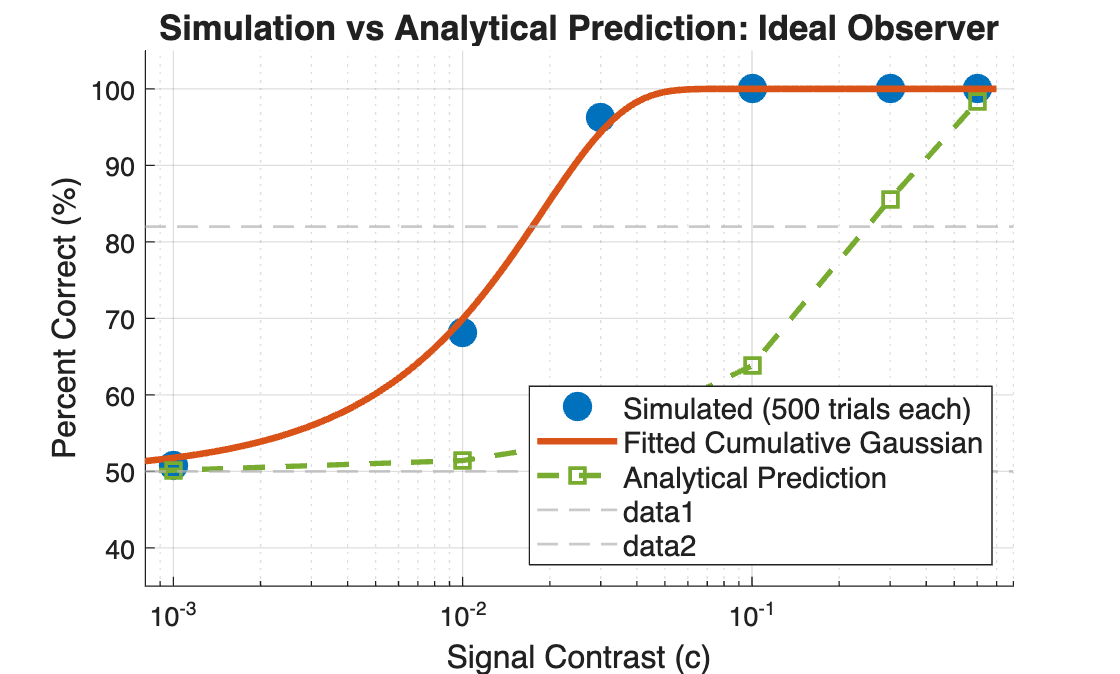

d_prime_ideal = contrast_levels / noise_sd;
pc_analytical = 100 * normcdf(d_prime_ideal / sqrt(2));

% Create a smooth fitted curve
contrast_fine = logspace(log10(0.0005), log10(0.7), 200);
pc_fitted = 100 * normcdf((contrast_fine - threshold_fitted) / slope_fitted);

% Plot everything together
figure('Name', 'Part C: Simulation vs Analytical Prediction');
hold on;

% Simulated data points
plot(contrast_levels, percent_correct, 'o', 'LineWidth', 2, 'MarkerSize', 9, ...
    'Color', [0, 0.447, 0.741], 'MarkerFaceColor', [0, 0.447, 0.741], ...
    'DisplayName', 'Simulated (500 trials each)');

% Fitted cumulative Gaussian
plot(contrast_fine, pc_fitted, '-', 'LineWidth', 2.5, ...
    'Color', [0.85, 0.325, 0.098], 'DisplayName', 'Fitted Cumulative Gaussian');

% Analytical prediction
plot(contrast_levels, pc_analytical, 's--', 'LineWidth', 2, 'MarkerSize', 7, ...
    'Color', [0.466, 0.674, 0.188], 'DisplayName', 'Analytical Prediction');

% Reference lines
yline(50, 'LineStyle', '--', 'Color', [0.7 0.7 0.7], 'LineWidth', 1);
yline(82, 'LineStyle', '--', 'Color', [0.7 0.7 0.7], 'LineWidth', 1);

xlabel('Signal Contrast (c)', 'FontSize', 12);
ylabel('Percent Correct (%)', 'FontSize', 12);
title('Simulation vs Analytical Prediction: Ideal Observer', 'FontSize', 13);
set(gca, 'XScale', 'log');
grid on;
ylim([35, 105]);
xlim([0.0008, 0.8]);
legend('Location', 'southeast', 'FontSize', 11);


drawnow;

**Comparing the curves:** How closely do the simulated data (blue circles) match the analytical prediction (green squares)? They should be nearly identical, confirming that our simulation correctly implements the matched-filter detector and the mathematics of signal detection theory.

**Why might they not match perfectly?** With a finite number of trials (500), there is sampling variability. If you re-ran the simulation with 50 trials per contrast instead of 500, you would see more scatter. If you used 5000 trials, the circles would be even closer to the analytical prediction.

**What happens to the curve if you double the noise standard deviation?** Doubling  $\sigma_{\text{noise}}$ halves the SNR at each contrast, so d' becomes smaller, making the task harder. The entire curve would shift rightward—higher contrasts would be needed to achieve the same percent correct.

**What if you double the spatial frequency of the Gabor?** With fixed image size, doubling spatial frequency creates more cycles. This can reduce signal energy (unless you adjust the window size), making the task harder again.

## =========================================================================

## D. PART 4: MEASURING HUMAN PERFORMANCE

## =========================================================================

Now we compare ideal observer performance to your own. Run the PsychoPy experiment (contrast-detection/contrast-detection.py) before this section. It uses the same stimulus parameters and saves a CSV file with columns: trial, contrast, signal_interval, response, correct, reaction_time

## D.1: Load and summarize the data

Select your data file using the file browser, or replace uigetfile with a hard-coded path if you prefer.

[fname, fpath] = uigetfile('contrast-detection/data/*.csv', 'Select your data file');
if isequal(fname, 0)
    error('No file selected.');
end
T = readtable(fullfile(fpath, fname));


% Parse PsychoPy 2IFC format:
%   contrast_1 / contrast_2: one is 0 (noise only), one is the signal contrast
%   key_resp_keys: 1 or 2 indicating which interval was chosen
contrast_vals = max(T.contrast_1, T.contrast_2);
signal_interval = 1 + double(T.contrast_2 > T.contrast_1);
response = T.key_resp_keys;
correct = double(response == signal_interval);

% Keep only valid trials (signal present, response recorded)
valid = ~isnan(contrast_vals) & contrast_vals > 0 & ~isnan(response);
contrast_vals = contrast_vals(valid);
correct = correct(valid);

% Compute percent correct at each contrast level
human_contrast_levels = unique(contrast_vals)';
n_human_contrasts = length(human_contrast_levels);
human_pc = zeros(1, n_human_contrasts);
for c_idx = 1:n_human_contrasts
    mask = contrast_vals == human_contrast_levels(c_idx);
    human_pc(c_idx) = 100 * mean(correct(mask));
end

for c_idx = 1:n_human_contrasts
    fprintf('  c=%.2f: %.1f%% correct\n', human_contrast_levels(c_idx), human_pc(c_idx));
end

  c=0.00: 75.0% correct
  c=0.00: 40.0% correct
  c=0.01: 45.0% correct
  c=0.03: 75.0% correct
  c=0.10: 95.0% correct
  c=0.30: 100.0% correct
  c=0.60: 95.0% correct


fprintf('\n');

## D.2: Fit a psychometric function

fit_fun_human = @(params) sum((human_pc - 100*normcdf((human_contrast_levels - params(1))/params(2))).^2);
fitted_human = fminsearch(fit_fun_human, [0.2, 0.05], optimset('Display', 'off'));

threshold_human   = fitted_human(1);
slope_human       = fitted_human(2);
threshold_82_human = threshold_human + slope_human * norminv(0.82);

fprintf('  Fitted threshold (c50): %.4f\n', threshold_human);

  Fitted threshold (c50): -0.0044


fprintf('  Threshold at 82%%: %.4f\n\n', threshold_82_human);

  Threshold at 82%: 0.0555



## D.3: Compute efficiency

Efficiency is the squared ratio of ideal to human threshold at the same criterion (82% correct). Values from 10-50% are typical for simple detection.

eta = (threshold_82 / threshold_82_human)^2;
fprintf('  Efficiency: %.1f%%\n\n', 100 * eta);

  Efficiency: 9.8%



## D.4: Plot human vs ideal

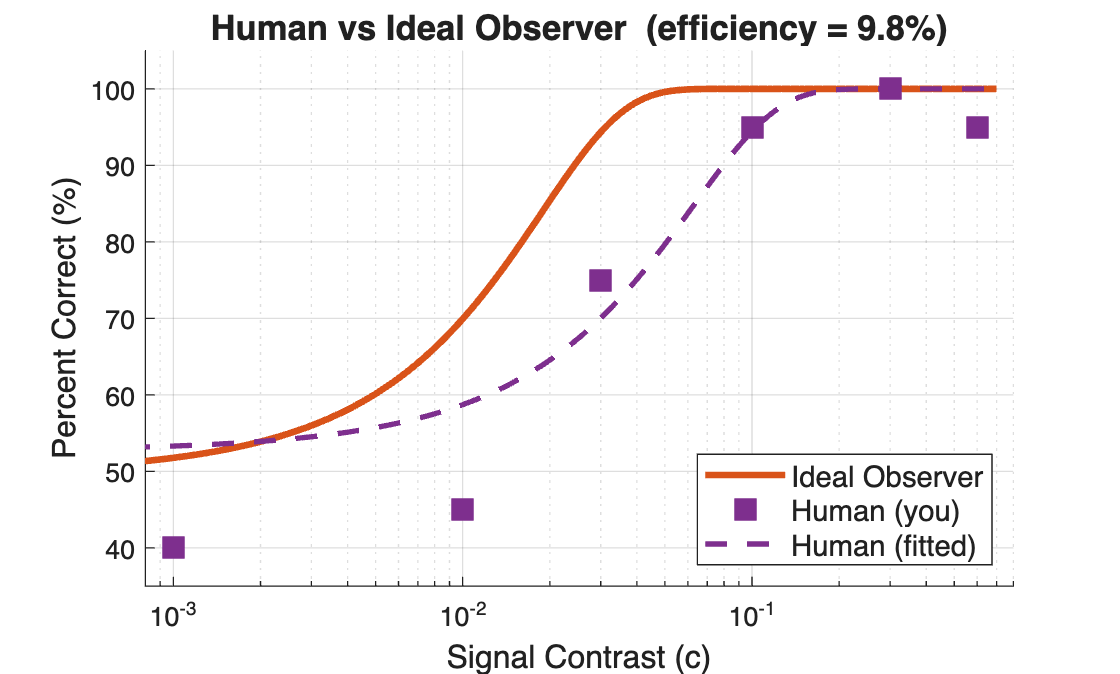

figure('Name', 'Part D: Human vs Ideal Observer');
hold on;

plot(contrast_fine, pc_fitted, '-', 'LineWidth', 2.5, ...
    'Color', [0.85, 0.325, 0.098], 'DisplayName', 'Ideal Observer');

plot(human_contrast_levels, human_pc, 's', 'LineWidth', 2, 'MarkerSize', 9, ...
    'Color', [0.494, 0.184, 0.556], 'MarkerFaceColor', [0.494, 0.184, 0.556], ...
    'DisplayName', 'Human (you)');

pc_human_fine = 100 * normcdf((contrast_fine - threshold_human) / slope_human);
plot(contrast_fine, pc_human_fine, '--', 'LineWidth', 2, ...
    'Color', [0.494, 0.184, 0.556], 'DisplayName', 'Human (fitted)');

xlabel('Signal Contrast (c)', 'FontSize', 12);
ylabel('Percent Correct (%)', 'FontSize', 12);
title(sprintf('Human vs Ideal Observer  (efficiency = %.1f%%)', 100*eta), 'FontSize', 13);
set(gca, 'XScale', 'log');
grid on;
ylim([35, 105]);
xlim([0.0008, 0.8]);
legend('Location', 'southeast', 'FontSize', 11);

drawnow;



## Part 5: Extensions (optional, for discussion)

Consider one or more of the following:

- **Suboptimal observers.** What happens if the observer uses the wrong template — e.g., a Gabor at a slightly different orientation or spatial frequency? Simulate a "mismatched filter" observer and compare its performance to the ideal. How much does a 15° orientation error cost?

- **Internal noise.** One model of human inefficiency adds internal Gaussian noise to the decision variable after the matched filter stage. Add a parameter `internal_noise_sd` to your simulation. Can you find a value that reproduces your measured efficiency?

- **Non-white noise.** Replace the white noise background with 1/f noise (which is more naturalistic). Does the matched filter remain ideal? What changes would you need to make?

## =========================================================================

## Helper Functions

## =========================================================================

function d_prime = dprime_from_pc(pc, task_type)
    % Convert percent correct to d' for a given task type
    % Input: pc = percent correct (0-100), task_type = 'YesNo' or '2AFC'
    % Output: d_prime = sensitivity measure
    
    if strcmp(task_type, 'YesNo')
        % Yes-no task: d' = 2 * Phi^-1(PC)
        d_prime = 2 * norminv(pc/100);
    elseif strcmp(task_type, '2AFC')
        % 2AFC task: d' = sqrt(2) * Phi^-1(PC)
        d_prime = sqrt(2) * norminv(pc/100);
    else
        error('Unknown task type. Use ''YesNo'' or ''2AFC''.');
    end
end

function efficiency = compute_efficiency(pc_human, pc_ideal)
    % Compute perceptual efficiency
    % Input: pc_human, pc_ideal = percent correct for human and ideal observer
    % Output: efficiency = (d'_human / d'_ideal)^2
    
    d_human = sqrt(2) * norminv(pc_human/100);
    d_ideal = sqrt(2) * norminv(pc_ideal/100);
    efficiency = (d_human / d_ideal)^2;
end